# AMCL SLAM

% =========================================================================
% MAPEO CON POSES CONOCIDAS (Usando /amcl_pose del rosbag)
% =========================================================================
clear; clc; close all;

%% 1. Cargar el archivo ROSBAG
filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con el nombre de tu archivo
disp('Abriendo archivo rosbag...');

Abriendo archivo rosbag...


bag = rosbag(filePath);

% Seleccionar los topics clave
bagScan = select(bag, 'Topic', '/scan');
bagAMCL = select(bag, 'Topic', '/amcl_pose');

% Extraer tiempos
time_scan = bagScan.MessageList.Time;
time_amcl = bagAMCL.MessageList.Time;

disp('Leyendo mensajes del rosbag...');

Leyendo mensajes del rosbag...


scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
amclMsgs = readMessages(bagAMCL, 'DataFormat', 'struct');

total_scan_msgs = length(scanMsgs);

%% 2. Inicialización del Mapa de Ocupación Log-Odds
map_res = 0.1; % Resolución de 10 cm por celda
x_min = -10; x_max = 35; % Ampliamos el límite derecho
y_min = -10; y_max = 35; % Ampliamos el límite superior
cols = round((x_max - x_min) / map_res);
rows = round((y_max - y_min) / map_res);

log_odds_map = zeros(rows, cols); 

% Probabilidades del sensor
p_occ = 0.99;  % Confianza en que hay pared 0.99
p_free = 0.4;  % Confianza en que está libre 0.4
l_occ = log(p_occ / (1 - p_occ));
l_free = log(p_free / (1 - p_free));

l_max = 20; % Aumentamos el "tope" de memoria de pared (antes 10)
l_min = -10;

% Parámetros geométricos del sensor (TF)
laser_offset_x   = 0.4296;    
laser_offset_y   = 0.2358;    
laser_offset_yaw = 0.7854;    
invertir_angulos = 1;

% Historial para dibujar la trayectoria
trajectory = zeros(total_scan_msgs, 3);

%% 3. Bucle Principal de Construcción de Mapa
disp('Iniciando proceso de mapeo usando poses de AMCL...');

Iniciando proceso de mapeo usando poses de AMCL...



for i = 1:total_scan_msgs
    current_time = time_scan(i);
    scan = scanMsgs{i};

    all_ranges = double(scan.Ranges);
    angle_min = double(scan.AngleMin);
    angle_inc = double(scan.AngleIncrement);
    range_min = double(scan.RangeMin);
    r_max_mapping = 6.0; % Alcance máximo útil del láser

    % =====================================================================
    % --- EXTRACCIÓN DE LA POSE DEL ROBOT (Sustituto del EKF) ---
    % Buscamos el mensaje de AMCL más cercano en el tiempo al scan actual
    % =====================================================================
    [~, idx_amcl] = min(abs(time_amcl - current_time));
    msg_amcl = amclMsgs{idx_amcl};
    
    % La pose de AMCL ya es global respecto al mapa, no necesitamos deltas
    rob_x = msg_amcl.Pose.Pose.Position.X;
    rob_y = msg_amcl.Pose.Pose.Position.Y;
    rob_yaw = quat2yaw_local(msg_amcl.Pose.Pose.Orientation);
    
    trajectory(i, :) = [rob_x, rob_y, rob_yaw];

    % =====================================================================
    % --- TRANSFORMACIÓN DEL SENSOR (TF) ---
    % =====================================================================
    % Trasladamos la pose del robot a la pose física del láser
    laser_x = rob_x + laser_offset_x * cos(rob_yaw) - laser_offset_y * sin(rob_yaw);
    laser_y = rob_y + laser_offset_x * sin(rob_yaw) + laser_offset_y * cos(rob_yaw);
    laser_yaw = wrapToPi(rob_yaw + laser_offset_yaw);
    
    % =====================================================================
    % --- ACTUALIZACIÓN DEL MAPA LOG-ODDS ---
    % =====================================================================
    all_angles = angle_min + (0:length(all_ranges)-1)' * angle_inc;
    
    laser_x_grid = round((laser_x - x_min) / map_res) + 1;
    laser_y_grid = round((laser_y - y_min) / map_res) + 1;
    
    for k = 1:length(all_ranges)
        r = all_ranges(k);
        a = all_angles(k);
        
        if isnan(r) || r < range_min
            continue;
        end
        
        es_impacto_valido = isfinite(r) && r <= r_max_mapping;
        r_trazado = min(r, r_max_mapping); 
        
        % Calcular punto final del rayo láser
        end_x = laser_x + r_trazado * cos(laser_yaw + (a * invertir_angulos));
        end_y = laser_y + r_trazado * sin(laser_yaw + (a * invertir_angulos));
        
        end_x_grid = round((end_x - x_min) / map_res) + 1;
        end_y_grid = round((end_y - y_min) / map_res) + 1;
        
        % Trazado de rayos (Bresenham)
        [ray_x, ray_y] = get_ray_cells(laser_x_grid, laser_y_grid, end_x_grid, end_y_grid);
        
        % Filtrar celdas fuera de los límites del mapa
        valid_ray_idx = ray_x > 0 & ray_x <= cols & ray_y > 0 & ray_y <= rows;
        ray_x = ray_x(valid_ray_idx);
        ray_y = ray_y(valid_ray_idx);
        
        if isempty(ray_x); continue; end
        
        lin_idx = sub2ind([rows, cols], ray_y, ray_x);
        
        % Actualizar Log-Odds
        if es_impacto_valido
            if length(lin_idx) > 1
                log_odds_map(lin_idx(1:end-1)) = log_odds_map(lin_idx(1:end-1)) + l_free;
            end
            log_odds_map(lin_idx(end)) = log_odds_map(lin_idx(end)) + l_occ;
        else
            log_odds_map(lin_idx) = log_odds_map(lin_idx) + l_free;
        end
    end

    if mod(i, 200) == 0
        fprintf('Procesados %d de %d scans...\n', i, total_scan_msgs);
    end
end

Procesados 200 de 10003 scans...
Procesados 400 de 10003 scans...
Procesados 600 de 10003 scans...
Procesados 800 de 10003 scans...
Procesados 1000 de 10003 scans...
Procesados 1200 de 10003 scans...
Procesados 1400 de 10003 scans...
Procesados 1600 de 10003 scans...
Procesados 1800 de 10003 scans...
Procesados 2000 de 10003 scans...
Procesados 2200 de 10003 scans...
Procesados 2400 de 10003 scans...
Procesados 2600 de 10003 scans...
Procesados 2800 de 10003 scans...
Procesados 3000 de 10003 scans...
Procesados 3200 de 10003 scans...
Procesados 3400 de 10003 scans...
Procesados 3600 de 10003 scans...
Procesados 3800 de 10003 scans...
Procesados 4000 de 10003 scans...
Procesados 4200 de 10003 scans...
Procesados 4400 de 10003 scans...
Procesados 4600 de 10003 scans...
Procesados 4800 de 10003 scans...
Procesados 5000 de 10003 scans...
Procesados 5200 de 10003 scans...
Procesados 5400 de 10003 scans...
Procesados 5600 de 10003 scans...
Procesados 5800 de 10003 scans...
Procesados 6000 de

disp('Mapeo Finalizado.');

Mapeo Finalizado.


# 4. Visualización

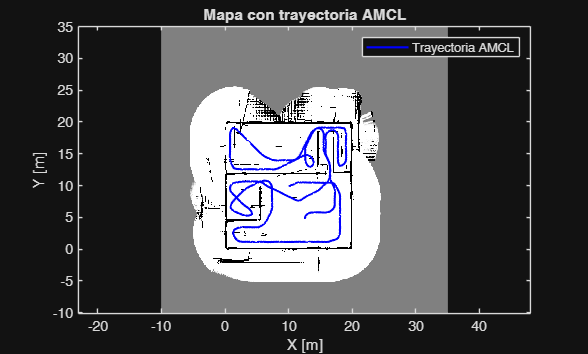

%% 4. Visualización
log_odds_map = max(min(log_odds_map, l_max), l_min);
prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));

figure('Name', 'Mapeo con trayectoria AMCL', 'NumberTitle', 'off');
imagesc([x_min x_max], [y_min y_max], 1 - prob_map); 
colormap(gray); 
axis equal xy; 
hold on;
plot(trajectory(:,1), trajectory(:,2), 'b-', 'LineWidth', 1.5);

title('Mapa con trayectoria AMCL');
legend('Trayectoria AMCL');
xlabel('X [m]'); ylabel('Y [m]');

#### Engrosamiento y Filtro de mediana

% %% 4. Visualización y Post-Procesamiento (Morfología Avanzada)
% log_odds_map = max(min(log_odds_map, l_max), l_min);
% prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));
% 
% % Quitamos el filtro de mediana (medfilt2) porque a veces adelgaza demasiado las paredes reales
% 
% % --- PASO A: Umbralización más compasiva ---
% % Bajamos el umbral a 0.55 para rescatar zonas donde el láser no pegó tantas veces
% paredes_crudas = prob_map > 0.55; 
% espacio_libre = prob_map < 0.45;  
% 
% % --- PASO B: Cierre Morfológico (IMCLOSE) ---
% % Creamos un pincel cuadrado de 3x3 píxeles
% se = strel('square', 3); 
% % Conectamos las paredes que estén rotas o fragmentadas
% paredes_conectadas = imclose(paredes_crudas, se);
% 
% % --- PASO C: Limpieza Inteligente ---
% % Como la zona importante ya se conectó, ahora sí borramos la basura pequeña
% pixeles_minimos = 12; 
% paredes_limpias = bwareaopen(paredes_conectadas, pixeles_minimos);
% 
% % --- PASO D: Construcción del Mapa Final (Trinario) ---
% mapa_final = 0.5 * ones(rows, cols); % Fondo gris (Desconocido)
% mapa_final(espacio_libre) = 0;       % Blanco (Espacio libre)
% mapa_final(paredes_limpias) = 1;     % Negro (Paredes sólidas confirmadas)
% 
% % --- Visualización ---
% figure('Name', 'Mapeo con AMCL (Cierre Morfológico)', 'NumberTitle', 'off');
% imagesc([x_min x_max], [y_min y_max], 1 - mapa_final); 
% colormap(gray); 
% axis equal xy; 
% hold on;
% plot(trajectory(:,1), trajectory(:,2), 'b-', 'LineWidth', 1.5);
% 
% title('Mapa Generado con AMCL (Zonas Importantes Rescatadas)');
% legend('Trayectoria AMCL');
% xlabel('X [m]'); ylabel('Y [m]');

## Solo filtro de mediana

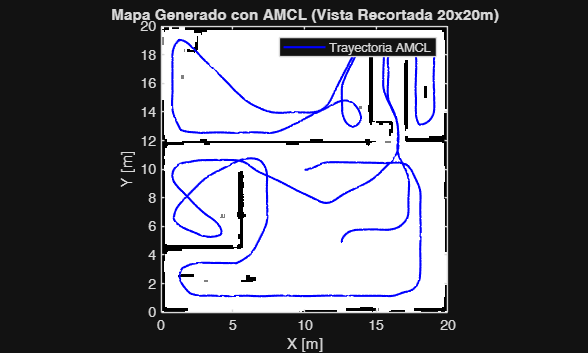

log_odds_map = max(min(log_odds_map, l_max), l_min);
prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));
% --- PASO A: Filtro de Mediana ---
% Suaviza el mapa general y elimina puntos aislados rápidamente
prob_map_filtered = medfilt2(prob_map, [3 3]);

% --- PASO B: Identificar Paredes y Espacio Libre ---
paredes_crudas = prob_map_filtered > 0.65; % Máscara lógica de posibles paredes %65
espacio_libre = prob_map_filtered < 0.35;  % Máscara lógica de espacio libre %35

% --- PASO C: Limpieza Morfológica ---
% Elimina agrupaciones de obstáculos que tengan menos de 15 píxeles conectados
pixeles_minimos = 15; 
paredes_limpias = bwareaopen(paredes_crudas, pixeles_minimos);

% --- PASO D: Construcción del Mapa Final (Trinario) ---
mapa_final = 0.5 * ones(rows, cols); % Fondo gris por defecto (Desconocido)
mapa_final(espacio_libre) = 0;       % Blanco (Espacio libre)
mapa_final(paredes_limpias) = 1;     % Negro (Paredes sólidas confirmadas)

% --- Visualización ---
figure('Name', 'Mapeo con Poses de AMCL (Limpio)', 'NumberTitle', 'off');
imagesc([x_min x_max], [y_min y_max], 1 - mapa_final); 
colormap(gray); 
axis equal xy; 
hold on;
plot(trajectory(:,1), trajectory(:,2), 'b-', 'LineWidth', 1.5);

% =========================================================================
% --- NUEVO: RECORTAR LA GRÁFICA A UNA ZONA DE 20x20 METROS ---
% =========================================================================
% El formato es axis([X_inicial  X_final  Y_inicial  Y_final])
% Si tu mapa principal está entre los 0 y 20 metros, usa esto:
axis([0 20 0 20]); 

% Nota: Si ves que el mapa te queda descentrado, puedes mover este 
% "cuadrado" de 20x20. Por ejemplo, si quieres que empiece en -5:
% axis([-5 15 -5 15]); 

title('Mapa Generado con AMCL (Vista Recortada 20x20m)');
legend('Trayectoria AMCL');
xlabel('X [m]'); ylabel('Y [m]');

Exportar mapa

%% 5. Exportar el Mapa Recortado a PNG
disp('Recortando y generando imagen PNG del mapa...');

Recortando y generando imagen PNG del mapa...



% --- 1. Definir los límites del recorte en metros ---
% Ajusta estos valores para encuadrar tu zona de 20x20m
crop_x_min = 0; 
crop_x_max = 20;
crop_y_min = 0; 
crop_y_max = 20;

% --- 2. Convertir metros a índices de la matriz ---
% Nos aseguramos de no salirnos de los límites reales del mapa original
idx_x_min = max(1, round((crop_x_min - x_min) / map_res) + 1);
idx_x_max = min(cols, round((crop_x_max - x_min) / map_res) + 1);
idx_y_min = max(1, round((crop_y_min - y_min) / map_res) + 1);
idx_y_max = min(rows, round((crop_y_max - y_min) / map_res) + 1);

% --- 3. Recortar la matriz ---
mapa_recortado = mapa_final(idx_y_min:idx_y_max, idx_x_min:idx_x_max);

% --- 4. Convertir a imagen y guardar ---
% Blanco (255) = Libre, Negro (0) = Pared, Gris (127) = Desconocido
imagen_png = uint8(255 * (1 - mapa_recortado));

% Invertimos verticalmente porque las imágenes se guardan de arriba hacia abajo
imagen_png = flipud(imagen_png);

% Guardar el archivo
nombre_archivo = 'mapa_recortado_20x20.png';
imwrite(imagen_png, nombre_archivo);

fprintf('¡Mapa recortado guardado como "%s" con éxito!\n', nombre_archivo);

¡Mapa recortado guardado como "mapa_recortado_20x20.png" con éxito!


% %% 5. Exportar el Mapa a PNG
% disp('Generando imagen PNG del mapa...');
% 
% % Convertimos la matriz (donde 1 es pared, 0 es libre y 0.5 es desconocido)
% % a un formato de imagen de 8 bits (0 a 255)
% % Blanco (255) = Libre, Negro (0) = Pared, Gris (127) = Desconocido
% imagen_png = uint8(255 * (1 - mapa_final));
% 
% % Invertimos la matriz verticalmente para que la imagen guardada 
% % coincida exactamente con la orientación que ves en la gráfica
% imagen_png = flipud(imagen_png);
% 
% % Guardamos el archivo en la misma carpeta donde está tu script
% nombre_archivo = 'mapa_limpio_mir.png';
% imwrite(imagen_png, nombre_archivo);
% 
% fprintf('¡Mapa guardado como "%s" con éxito!\n', nombre_archivo);


%% ========================================================================
% FUNCIONES AUXILIARES
% =========================================================================
function [x, y] = get_ray_cells(x1, y1, x2, y2)
    n_points = max(abs(x2 - x1), abs(y2 - y1)) + 1;
    x = round(linspace(x1, x2, n_points));
    y = round(linspace(y1, y2, n_points));
end

function yaw = quat2yaw_local(q)
    yaw = atan2(2*(q.W*q.Z + q.X*q.Y), 1 - 2*(q.Y^2 + q.Z^2));
end
